# Linear System - Modeling and Simulation

## Time-invariant Discrete-time Nonlinear System

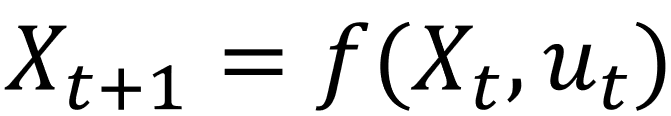

                 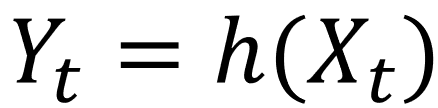

- **X: State**

- **Y: Output**

- **f: System function**

- **h: Measure funciton**

- **u: Input**

## **Nonlinear Model – Dead Reckoning (DR)**

### **problem discription**

The simulation targets are a **dynamic state vector (x, y, 𝜓(heading))** of a vehicle and **measurement (output) vector (r, θ) ** on two-dimension space (X and Y).

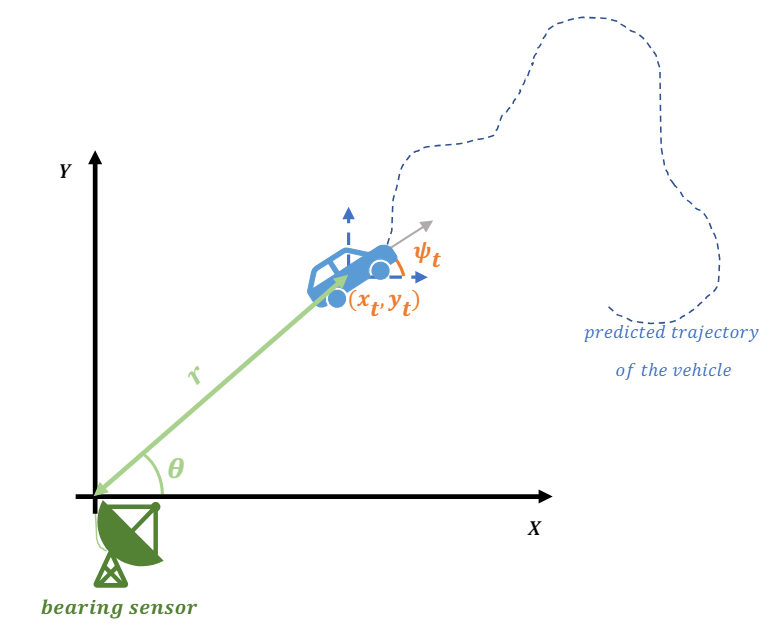

### Motion model - **Dead Reckoning (DR)**

A nonlinear discrete vehicle motion model (dead reckoning, DR) with **velocity(𝑽) and yawrate(𝝍̇) inputs** can be represented as follow:

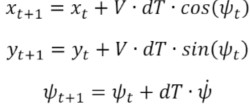

- x_t , y_t : vehicle's X and Y **position** at t

- V: vehicle's **velocity **

- v_x, v_y: vehicle's X and Y **velocity** at t

- 𝝍: vehicle's yaw

- delta_t: **sampling time**

### **State Space Equation**

clc; clear; close all; 
load('nonlinear_system_mat_file.mat');

### Simulation - Dead Reckoning Model Result

Input

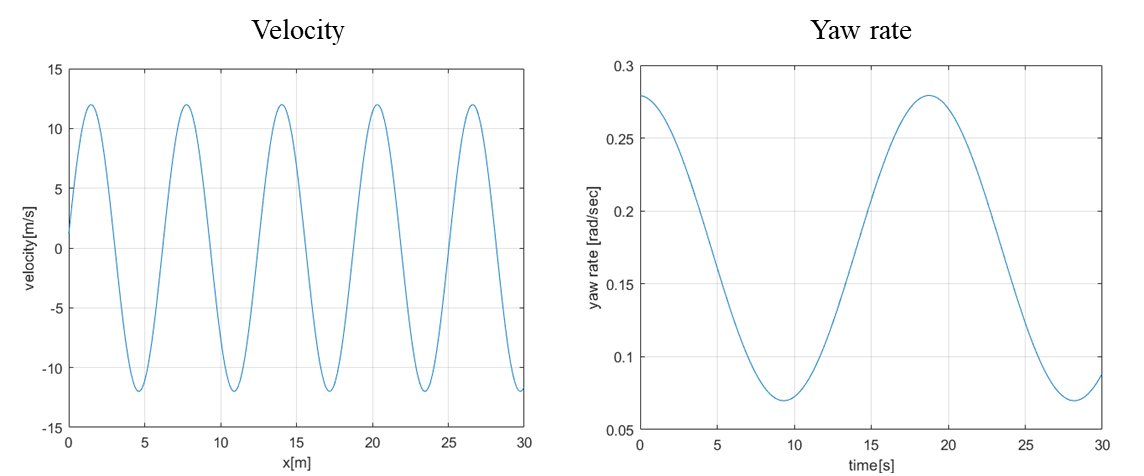

Target state

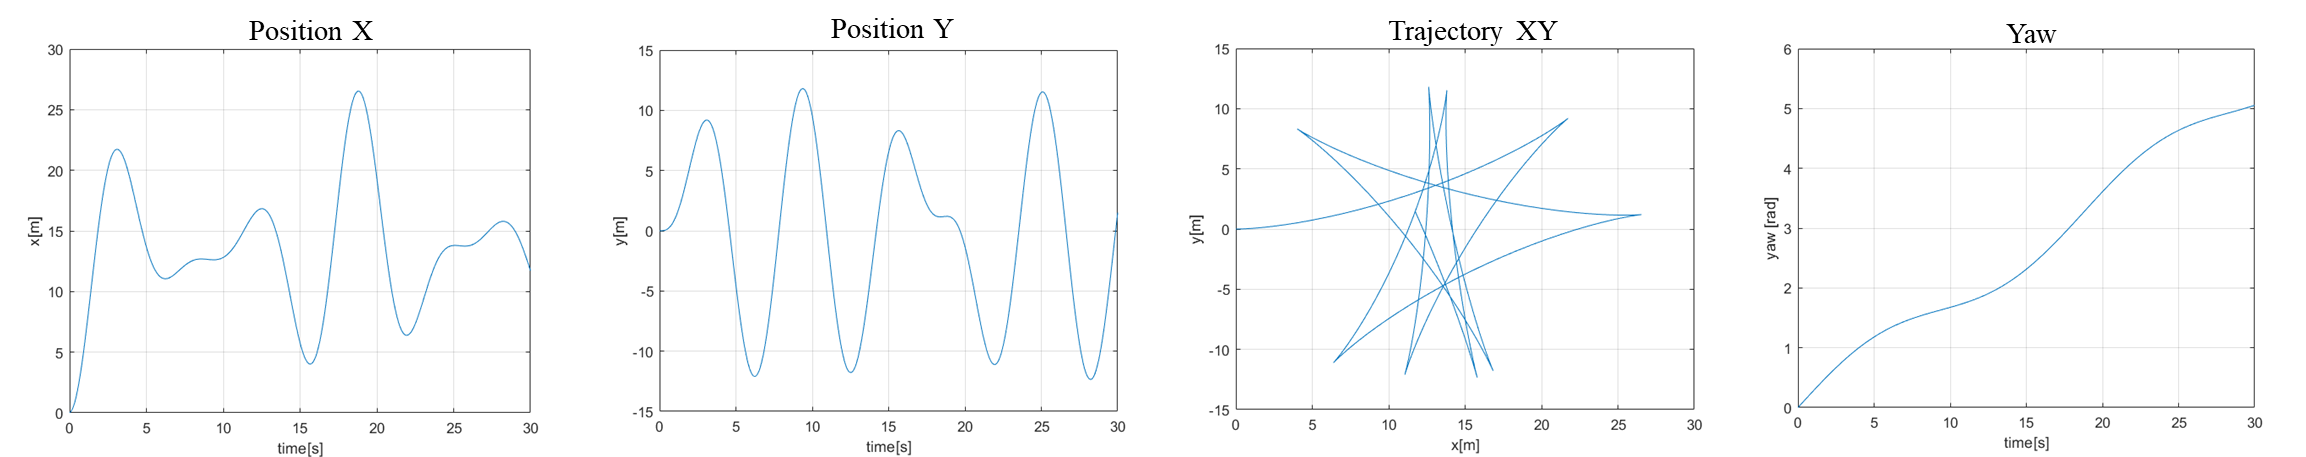

Target measurement

#### System time propagation

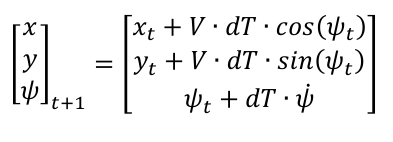

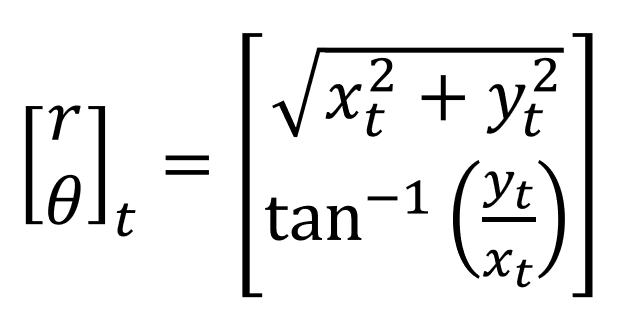

## Determine the function 'f' and 'h' below the script

### Simulation - Dead Reckoning model

#### Initial condition

- ∆t: 0.1 second

- initial positoin x = 0 m, y = 0 m

- initial yaw = 0 [rad]

- simulation time: 0 to 30 seconds

STATE_ORDER = 3; % [position x, position y, yaw]
OUTPUT_ORDER = 2; % [range, theta]
state = zeros([STATE_ORDER, total_process_steps]);
output = zeros([OUTPUT_ORDER, total_process_steps]);

isFirstStep = true;

for idx=1:total_process_steps
    if isFirstStep == true
        state(:,idx) = [0; 0; 0];
        isFirstStep = false;
    else
        % To do 
            % fill the state using f equation
        state(:,idx) = f(state(:,idx-1),input(:,idx-1),delta_t);
    end
    % To do 
        % fill the state using state and H matrix
    output(:,idx) = h(state(:,idx));
end

## Visualize Result

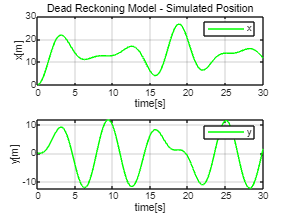

figure('Name','Dead Reckoning Model - Simulated Position','Position',[100,100,840,630]);

hold on; 

subplot(2,1,1)
plot(time, state(1,:), 'g');
legend('x'); 
xlabel('time[s]'); ylabel('x[m]'); grid on;
title ('Dead Reckoning Model - Simulated Position');

subplot(2,1,2)
plot(time, state(2,:), 'g');
legend('y');
xlabel('time[s]'); ylabel('y[m]'); grid on;


hold off

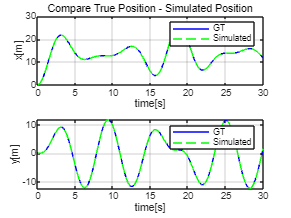


figure('Name','Compare True Position - Simulated Position','Position',[100,100,840,630]);

hold on; 

subplot(2,1,1)
plot(time, pose(1,:), 'b', time, state(1,:), 'g--');
legend('GT', 'Simulated'); 
xlabel('time[s]'); ylabel('x[m]'); grid on;
title ('Compare True Position - Simulated Position')

subplot(2,1,2)
plot(time, pose(2,:), 'b', time, state(2,:), 'g--');
legend('GT', 'Simulated');
xlabel('time[s]'); ylabel('y[m]'); grid on;

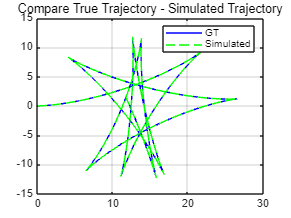


figure

plot(pose(1,:), pose(2,:), 'b'); hold on; grid on;
plot(state(1,:), state(2,:), 'g--'); hold on; grid on;
legend('GT', 'Simulated');
title ('Compare True Trajectory - Simulated Trajectory')

hold off

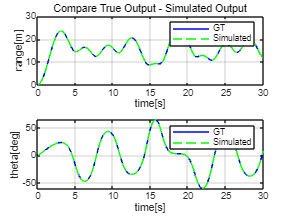


figure('Name','Compare True Output - Simulated Output','Position',[100,100,840,630]);

hold on; 

subplot(2,1,1)
plot(time, measurement(1,:), 'b', time, output(1,:), 'g--');
legend('GT', 'Simulated'); 
xlabel('time[s]'); ylabel('range[m]'); grid on;
title ('Compare True Output - Simulated Output')

subplot(2,1,2)
plot(time, rad2deg(measurement(2,:)), 'b', time, rad2deg( output(2,:)), 'g--');
legend('GT', 'Simulated');
xlabel('time[s]'); ylabel('theta[deg]'); grid on;


hold off

## function

function next_state = f(state,input,dt) % function input: state, input, dt
    % Determine the full equation
    next_state = [state(1)+input(1)*dt*cos(state(3));
        state(2)+input(1)*dt*sin(state(3));
        state(3)+dt*input(2)];
end

function output = h(state) % function input: state
    % Determine the full equation, use atan2(Y,X) function
    output = [sqrt(state(1)^2+state(2)^2) ; ...
              atan2(state(2),state(1)) ];
end